# High Voltage Battery - Simulation Case

## Random current

mdl = "BatteryHV_harness_model";
load_system(mdl)

% Load model parameters.
BatteryHV_harness_setup

% Select battery model.
% BatteryHV_useRefsub_Basic
BatteryHV_useRefsub_SystemTable

Model: BatteryHV_harness_model
Setting up referenced subsystem: BatteryHV_refsub_SystemTable


% Setup simulation case.
BatteryHV_loadSimulationCase_Random( ...
  RandomSeed = 125, ...
  NumTransitions = 20, ...
  InitialSOC_pct = 50 );

Setting up simulation...
Simulation case: Random input
Setting simulation stop time to 2206 sec.
Setting block parameters for input blocks...
Setting initial conditions...
initial.hvBattery_SOC_pct = 50
initial.hvBattery_SOC_normalized = 0.5
initial.hvBattery_Charge_Ahr = 88.2353
initial.hvBattery_Temperature_K = 293.15
initial.ambientTemp_K = 293.15


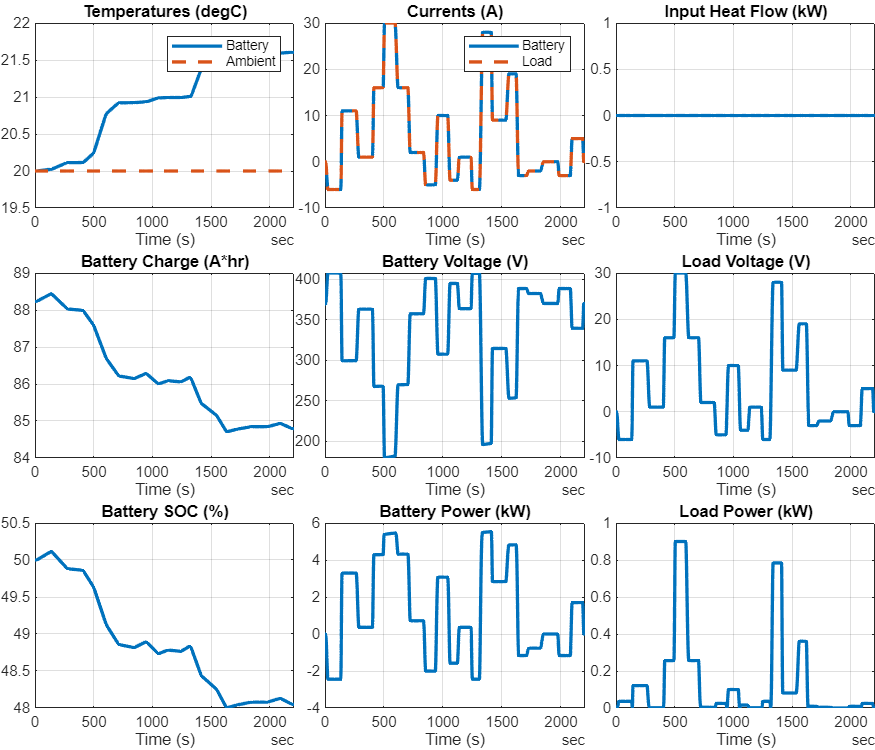

% Run simulation.
simOut = sim(mdl);

% Collect logged signals and visualize.
% The basic version of the battery block does not simulate battery temperature.
logged_signals = extractTimetable(simOut.logsout);
BatteryHV_plotResults(logged_signals);

*Copyright 2023 The MathWorks, Inc.*